imageDir = fullfile(matlabroot, 'toolbox', 'vision', 'visiondata', 'stopSignImages');
addpath(imageDir);

load('stopSignsAndCarsGroundTruth.mat','stopSignsAndCarsGroundTruth')

stopSignGroundTruth = selectLabelsByName(stopSignsAndCarsGroundTruth,'stopSign');

trainingData = objectDetectorTrainingData(stopSignGroundTruth);
summary(trainingData)

Variables:

    imageFilename: 41×1 cell array of character vectors

    stopSign: 41×1 cell



acfDetector = trainACFObjectDetector(trainingData,'NegativeSamplesFactor',2);

ACF Object Detector Training
The training will take 4 stages. The model size is 34x31.
Sample positive examples(~100% Completed)
Compute approximation coefficients...Completed.
Compute aggregated channel features...Completed.
--------------------------------------------
Stage 1:
Sample negative examples(~100% Completed)
Compute aggregated channel features...Completed.
Train classifier with 42 positive examples and 84 negative examples...Completed.
The trained classifier has 19 weak learners.
--------------------------------------------
Stage 2:
Sample negative examples(~100% Completed)
Found 84 new negative examples for training.
Compute aggregated channel features...Completed.
Train classifier with 42 positive examples and 84 negative examples...Completed.
The trained classifier has 20 weak learners.
--------------------------------------------
Stage 3:
Sample negative examples(~100% Completed)
Found 84 new negative examples for training.
Compute aggregated channel features...Complete

I = imread('stopSignTest.jpg');
bboxes = detect(acfDetector,I);

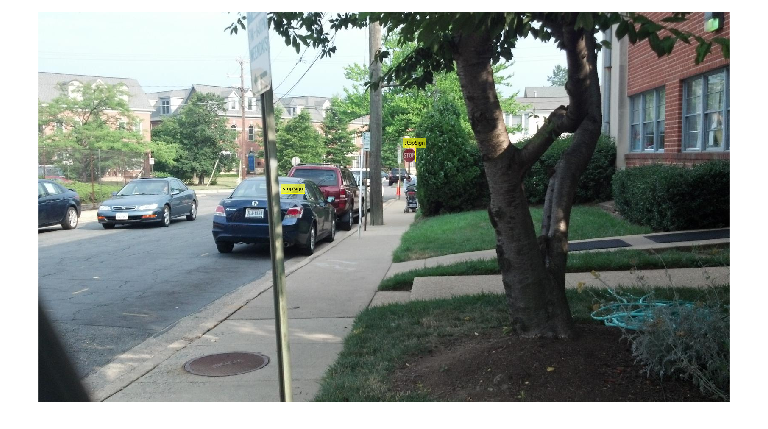

annotation = acfDetector.ModelName;
I = insertObjectAnnotation(I,'rectangle',bboxes,annotation);
figure 
imshow(I)

rmpath(imageDir); 